# 数字图像处理 作业2 (3/11)

阮泉源 201930033629 第二章

## 1.1 普通的灰度变换增强

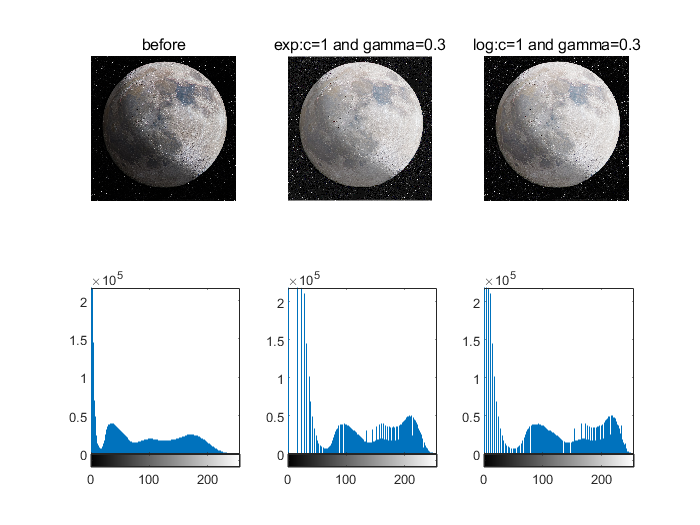

im_moon = imread('moon.jpeg');

im_moon_norm = double(im_moon)/(L-1);

im_exp = uint8(255*im_moon_norm.^0.5);
im_log = uint8(255*log10(9*im_moon_norm+1));

figure;
subplot(2,3,1)
imshow(im_moon)
title('before')

subplot(2,3,2)
imshow(im_exp)
title('exp:c=1 and gamma=0.3')

subplot(2,3,3)
imshow(im_log)
title('log:c=1 and gamma=0.3')

subplot(2,3,4)
imhist(im_moon)

subplot(2,3,5)
imhist(im_exp)

subplot(2,3,6)
imhist(im_log)

结果分析：

    原始的月亮图片中，左下角 的阴影部分较深，显示的效果不好。

    经过灰度变换增强后，可以看到左下角的区域有着明显的改善。

## 1.2 一般的灰度变换增强

    为做实验3，需要对图片的灰度级进行压缩。将灰度级的频数集中在中间区域。所以我们需要将图片归一为0~1之间的数值，然后确定一个函数，对于${{T\left(r\right)=\sum_n \;a}_n r}^n$的一元n次方程，取n=5，假设有$T\prime \left(0\right)=T\prime \left(1\right)=5$，且$T\prime \left(0\ldotp 5\right)=0\ldotp 5$，求解可以得到多项式的系数。

    再进行灰度压缩前首先要将灰度值归一化到0~1之间，利用上面得到的函数$T\left(r\right)$进行映射，可以得到灰度级压缩后的图片。

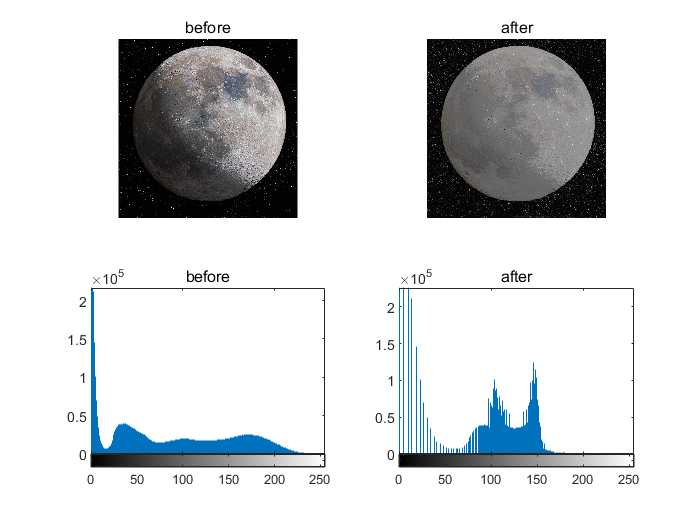

A = [1 1 1 1 1;5 4 3 2 1;
    0.5^5 0.5^4 0.5^3 0.5^2 0.5^1;
    5*0.5^4 4*0.5^3 3*0.5^2 2*0.5^1 1*0.5^0;
    0 0 0 0 1];
B = [1; 5; 0.5; 0.5; 5];
R = A\B;
x = 0:0.01:1;
y = R(1)*x.^5+R(2)*x.^4+R(3)*x.^3+R(4)*x.^2+R(5)*x.^1;

% 灰度压缩
im_moon_norm = double(im_moon)/(L-1);

im_moon_zip = R(1)*im_moon_norm.^5+R(2)*im_moon_norm.^4+R(3)*im_moon_norm.^3+R(4)*im_moon_norm.^2+R(5)*im_moon_norm.^1;

im_moon_zip = uint8(255*im_moon_zip);

figure;
subplot(2,2,1)
imshow(im_moon)
title('before')

subplot(2,2,2)
imshow(im_moon_zip)
title('after')

subplot(2,2,3)
imhist(im_moon)
title('before')

subplot(2,2,4)
imhist(im_moon_zip)
title('after')

## 2.计算直方图

    灰度统计直方图是对灰度等级的统计频数，可以由$p\left(r_k \right)=\frac{n_k }{n}$计算得出。

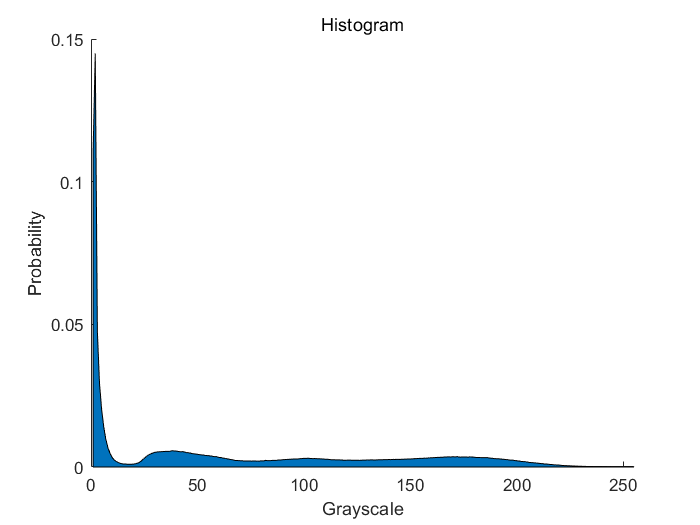

im_moon = imread('moon.jpeg');

im_moon = rgb2gray(im_moon);

L = 256;

hist_list = zeros(1,L);
for i=1:L 
    hist_list(i) = sum(sum(im_moon(:,:)==(i-1)));
end

[w,h] = size(im_moon);
N = w*h;
hist_list = hist_list/N;

figure;
hold on;
area(hist_list)
hold off;


xlim([0,255])
ylabel('Probability')
xlabel('Grayscale')
title('Histogram')

结果分析：

    直方图如图所示。拍摄的月亮的图片灰度主要分布在低灰度区域，缺乏高灰度区域。